# Sounding Data

clearvars;

## Input data files


data = 'Zac Acer\6.12.2020\';
datainput = 'digitalsonde2020061212Z_full.csv';
gpsinput = 'groundtrack2020061212Z_full.txt';
gpsdata = append(data,gpsinput);
atmdata = append(data,datainput);
Sounding_data = RS92_import(atmdata);
GPS_data = RS92_GPS_import(gpsdata);


## Sync data


sFrame = table2array(Sounding_data(:,1));
gFrame = table2array(GPS_data(:,1));
Sounding.Pressure = table2array(Sounding_data(:,2));
GPS.Alt = table2array(GPS_data(:,4));

if gFrame(1)<sFrame(1)
    i = find(gFrame==sFrame(1),1);
    GPS_data = circshift(GPS_data,length(gFrame)-i+1,1);
else
    i = find(sFrame==gFrame(1),1);
    Sounding_data = circshift(Sounding_data,length(sFrame)-i+1,1);
end

if length(gFrame)>length(sFrame)
    GPS_data = GPS_data(1:length(sFrame),:);
else
    Sounding_data = Sounding_data(1:length(gFrame),:);
end


## Create Data structure for data processing


Sounding.Pressure = table2array(Sounding_data(:,2));
Sounding.Temp = table2array(Sounding_data(:,3));
Sounding.Humidity = table2array(Sounding_data(:,4));
GPS.Alt = table2array(GPS_data(:,4));
GPS.Time = table2array(GPS_data(:,6));
GPS.Lat = table2array(GPS_data(:,2));
GPS.Lon = table2array(GPS_data(:,3));

## minor noise removel


% remove bad gps altutude data

GPS.Alt = medfilt1(GPS.Alt,10);
GPS.Lon = medfilt1(GPS.Lon);
GPS.Lat = medfilt1(GPS.Lat);

% for i = 1:length(GPS.Alt);
%     if GPS.Alt(i) <= 0;
%         GPS.Alt(i) = NaN;
%     else
%         GPS.Alt(i) = GPS.Alt(i);
%     end
%     if GPS.Alt(i) > 10000;
%         GPS.Alt(i) = NaN;
%     else
%         GPS.Alt(i) = GPS.Alt(i);
%     end
%     if GPS.Lat(i) < 36.3 && GPS.Lat(i) > 36;
%         GPS.Lat(i) = GPS.Lat(i);
%     else
%         GPS.Lat(i) = NaN;
%     end
%     if GPS.Lon(i) < -97 ;
%         GPS.Lon(i) = NaN;
%     else
%         GPS.Lon(i) = GPS.Lon(i);
%     end
% end


## Plot

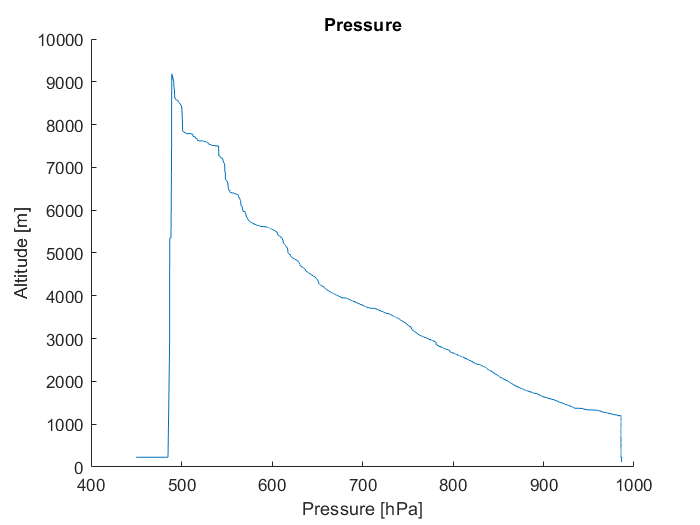


figure(2)
clf;
hold on;
plot(Sounding.Pressure,GPS.Alt)
title('Pressure');
xlabel('Pressure [hPa]');
ylabel('Altitude [m]');

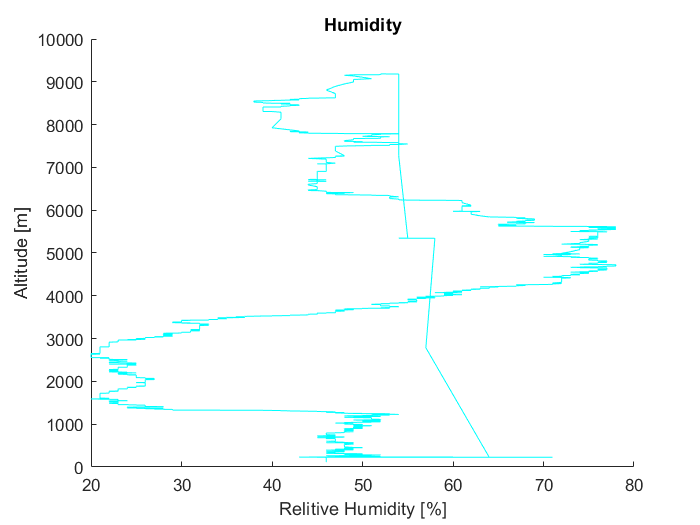


figure (3)
clf;
hold on;
plot(Sounding.Humidity,GPS.Alt,'c')
title('Humidity');
xlabel('Relitive Humidity [%]');
ylabel('Altitude [m]');

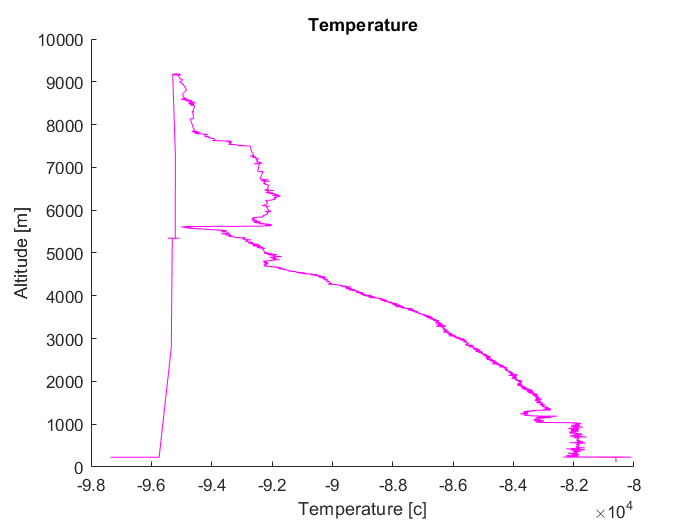


figure (3)
clf;
hold on;
plot(Sounding.Temp,GPS.Alt,'m')
title('Temperature');
xlabel('Temperature [c]');
ylabel('Altitude [m]');

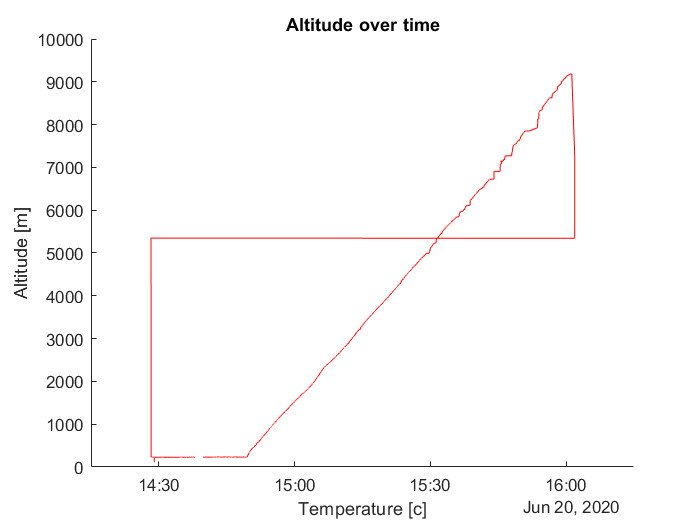


figure (4)
clf;
hold on;
plot(GPS.Time,GPS.Alt,'r')
title('Altitude over time');
xlabel('Temperature [c]');
ylabel('Altitude [m]');

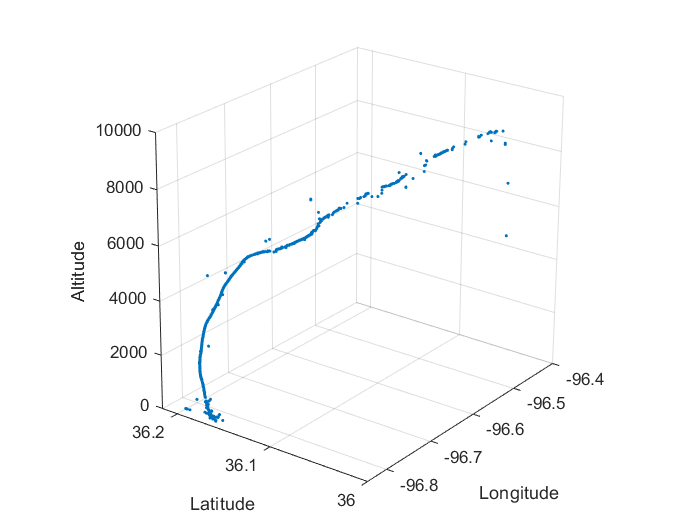


% figure (5)
% clf;
% hold on;
% grid on;
% plot3(GPS.Lon,GPS.Lat,GPS.Alt,'.')
% xlabel('Longitude');
% ylabel('Latitude');
% zlabel('Altitude')

figure5 = figure('NumberTitle','off','Name','Figure');
axes1 = axes('Parent',figure5);
hold(axes1,'on');
plot3(GPS.Lon,GPS.Lat,GPS.Alt,'Marker','.','LineStyle','none');
zlabel('Altitude');
ylabel('Latitude');
xlabel('Longitude');

% xlim(axes1,[-96.8531561974077 -96.4531561974077]);
% ylim(axes1,[36.0168497996625 36.2668497996625]);
grid(axes1,'on');
hold(axes1,'off');
set(axes1,'CameraPosition',...
    [-99.1867397261753 34.931719266041 38838.3083321074],'CameraUpVector',...
    [0.496725568569105 0.237253980589442 36820.1941380976],'CameraViewAngle',...
    9.60129144001422,'DataAspectRatio',[1.59999999999997 1 40000],'Projection',...
    'perspective');

## GPS Bearing test



dL = GPS.Lon(1)-GPS.Lon;
X = cos(GPS.Lat).*sin(dL);
Y = cos(GPS.Lat(1)).*sin(GPS.Lat)-sin(GPS.Lat(1)).*cos(GPS.Lat).*cos(dL);
b = atan2(X, Y);
bearing = (b.*(180/pi));
for i = 1:length(bearing)
    if bearing(i)<0
        bearing(i)=bearing(i)+360;
    end
end



## plot gif

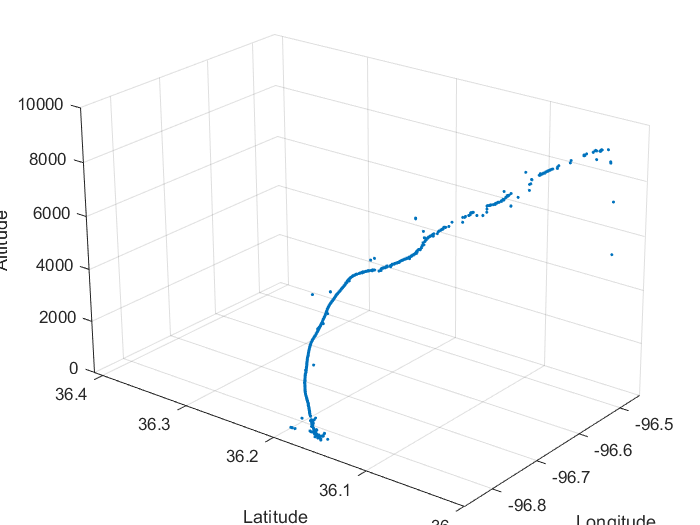


figure(6)
plot3(GPS.Lon,GPS.Lat,GPS.Alt,'r.');
xlim(axes1,[-96.86 -96.45]);
ylim(axes1,[36 36.41]);
title('GPS Data')
xlabel('Altitude')
ylabel('Latitude')
zlabel('Altitude')
legend('Data')
grid on
az = 0;
el = 90;
view([az,el]);
degStep = 5;
detlaT = 0.1;
fCount = 71;
f = getframe(gcf);

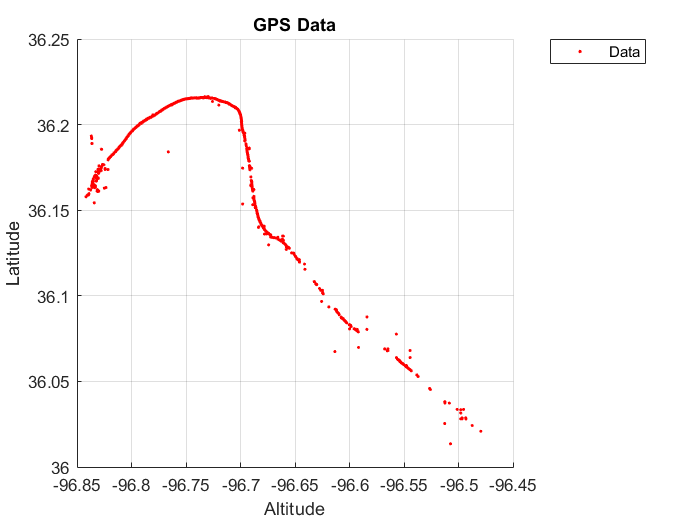

[im,map] = rgb2ind(f.cdata,256,'nodither');
im(1,1,1,fCount) = 0;
k = 1;
% spin 45°
for i = 0:-degStep:-45
  az = i;
  ([az,el]);
  f = getframe(gcf);
  im(:,:,1,k) = rgb2ind(f.cdata,map,'nodither');
  k = k + 1;
end
% tilt down
for i = 90:-degStep:15
  el = i;
  view([az,el]);
  f = getframe(gcf);
  im(:,:,1,k) = rgb2ind(f.cdata,map,'nodither');
  k = k + 1;
end
% spin left
for i = az:-degStep:-90
  az = i;
  view([az,el]);
  f = getframe(gcf);
  im(:,:,1,k) = rgb2ind(f.cdata,map,'nodither');
  k = k + 1;
end
% spin right
for i = az:degStep:0
  az = i;
  view([az,el]);
  f = getframe(gcf);
  im(:,:,1,k) = rgb2ind(f.cdata,map,'nodither');
  k = k + 1;
end
% tilt up to original
for i = el:degStep:90
  el = i;
  view([az,el]);
  f = getframe(gcf);
  im(:,:,1,k) = rgb2ind(f.cdata,map,'nodither');
  k = k + 1;
end

imwrite(im,map,'Animation.gif','DelayTime',detlaT,'LoopCount',inf)